clc; clear;
dsFolder = "p_dataset_26";
subFolder = ["0", "4", "7", "8", "A", "D", "H"];
categories = ["0", "4", "7", "8", "A", "D", "H"];

allData = table('Size', [0, 2], 'VariableTypes', {'cell', 'cell'}, 'VariableNames', {'Image', 'Label'});

for i = 1:length(subFolder)
    folderPath = fullfile(dsFolder, subFolder(i));
    pngFiles = dir(fullfile(folderPath, "*.png"));

    for j = 1:length(pngFiles)
        pngFilePath = fullfile(folderPath, pngFiles(j).name);
        image = imread(pngFilePath);
        thresholdValue = graythresh(image);
        image = imbinarize(image, thresholdValue);
        allData = [allData; {image, categories(i)}];
    end
end

% convert images to features
numImages = size(allData, 1);
imageSize = size(allData.Image{1});
features = zeros(numImages, prod(imageSize));

for i = 1:numImages
    image = allData.Image{i};
    features(i, :) = image(:)';
end

labels = categorical(allData.Label);

% split data into training and test set
cv = cvpartition(labels, 'HoldOut', 0.25);
idx = cv.test;
trainIdx = training(cv);
testIdx = test(cv);
trainFeatures = features(trainIdx, :);
trainLabels = labels(trainIdx, :);
testFeatures = features(testIdx, :);
testLabels = labels(testIdx, :);

## Train the SVM classifier

% select from the 4 KernelFunctions
kernel = ["linear", "gaussian", "rbf", "polynomial"];
numKernel = numel(kernel);
svmTemplate = cell(1, numKernel);
svmClassifier = cell(1, numKernel);
predictedLabels = cell(1, numKernel);
confusionMatrix = cell(1, numKernel);
accuracy = zeros(1, numKernel);
trainingTime = zeros(1, numKernel);

for k = 1:numKernel
    % start timing
    tic;

    % train a SVM classifier
    svmTemplate{k} = templateSVM('KernelFunction', kernel(k), "Type", "classification");
    svmClassifier{k} = fitcecoc(trainFeatures, trainLabels, 'Learners', svmTemplate{k});

    % Stop timing and calculate training time
    trainingTime(k) = toc;

    % Predict labels for the test set
    predictedLabels{k} = predict(svmClassifier{k}, testFeatures);

    % Evaluate the classifier's performance
    confusionMatrix{k} = confusionmat(testLabels, predictedLabels{k});
    accuracy(k) = sum(diag(confusionMatrix{k})) / sum(confusionMatrix{k}(:));

    % print the kernel type, accuracy and training time
    fprintf('Kernel Type: %s, Accuracy: %.2f%%, Training Time: %.2f seconds\n', ...
        kernel(k), accuracy(k) * 100, trainingTime(k));
end

Kernel Type: linear, Accuracy: 95.72%, Training Time: 5.07 seconds
Kernel Type: gaussian, Accuracy: 30.86%, Training Time: 17.67 seconds
Kernel Type: rbf, Accuracy: 30.86%, Training Time: 16.42 seconds
Kernel Type: polynomial, Accuracy: 80.18%, Training Time: 74.58 seconds


## Plot the results

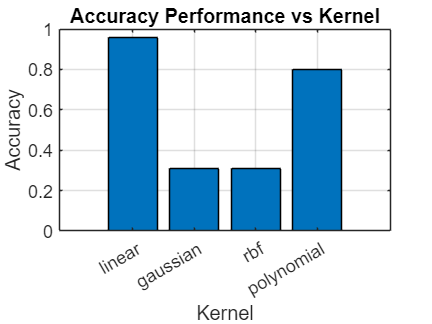

eps_filename = 'results/svm.eps'

Saved results/svm.eps


% Accuracy Performance vs Kernel
bar(accuracy);
xticks(1:numKernel);
xticklabels(kernel);
xlabel('Kernel');
ylabel('Accuracy');
ylim([0, 1]); 
title('Accuracy Performance vs Kernel');
grid on;


% Save the plot as an EPS file
eps_filename = 'results/svmAccuracyVsKernel'
saveas(gcf, eps_filename, 'epsc');
fprintf('Saved %s\n', eps_filename);

% Training Time vs Kernel
bar(trainingTime);
xticks(1:numKernel);
xticklabels(kernel);
xlabel('Kernel');
ylabel('Training Time (s)'); 
title('Training Time vs Kernel');
grid on;

% Save the plot as an EPS file
eps_filename = 'results/svmTrainingTimeVsKernel.eps'

eps_filename = 'results/svmTrainingTimeVsKernel.eps'

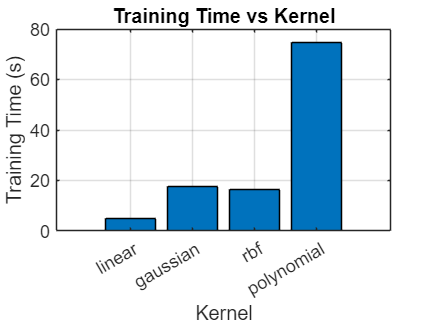

saveas(gcf, eps_filename, 'epsc');

fprintf('Saved %s\n', eps_filename);

Saved results/svmTrainingTimeVsKernel.eps


## Confusion Matrix

% Calculate precision, recall, and F1-score
truePositive = confusionMatrix{1}(1, 1);
falsePositive = confusionMatrix{1}(2, 1);
falseNegative = confusionMatrix{1}(1, 2);

precision = truePositive / (truePositive + falsePositive);
recall = truePositive / (truePositive + falseNegative);
f1Score = 2 * (precision * recall) / (precision + recall);

fprintf('Precision: %.2f\n', precision);

Precision: 0.98


fprintf('Recall: %.2f\n', recall);

Recall: 1.00


fprintf('F1-Score: %.2f\n', f1Score);

F1-Score: 0.99


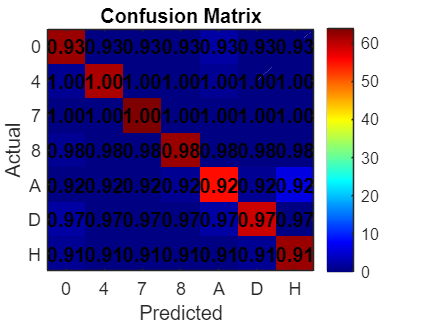

% Visualize the confusion matrix using imagesc and annotate precision
figure;
imagesc(confusionMatrix{1});
colorbar;
colormap('jet'); % You can change the colormap as needed
title('Confusion Matrix');
xlabel('Predicted');
ylabel('Actual');
xticks(1:numel(categories));
xticklabels(categories);
yticks(1:numel(categories));
yticklabels(categories);

% Calculate and annotate precision for each class
for i = 1:numel(categories)
    for j = 1:numel(categories)
        precision = confusionMatrix{1}(i, i) / sum(confusionMatrix{1}(:, i));
       text(j, i, sprintf('%.2f', precision), 'HorizontalAlignment', ...
           'center', 'VerticalAlignment', 'middle', 'Color', 'k', 'FontWeight', 'bold');
    end
end

## Hyperparams Tuning

% Parameter ranges
C = [0.1, 1, 10, 100, 1000];
sigma = [0.1, 1, 10, 100, 1000];

% Initialize the best parameters and highest score
bestC = 0;
bestSigma = 0;
bestScore = 0; % Initialize bestScore to Inf for correct comparison
scores = zeros(length(C), length(sigma)); % Store scores
times = zeros(length(C), length(sigma)); % Store training times

for i = 1:length(C)
    for j = 1:length(sigma)
        % Start the timer
        tic;

        % Configure the SVM model
        svmTemplateBest = templateSVM('KernelFunction', 'linear', 'BoxConstraint', C(i), 'KernelScale', sigma(j));
        svmClassifierBest = fitcecoc(trainFeatures, trainLabels, 'Learners', svmTemplateBest);

        % Stop the timer and get the elapsed time
        elapsedTime = toc;
        times(i,j) = elapsedTime; % Store training time

        % Predict labels for the test set
        predictedLabels = predict(svmClassifierBest, testFeatures);

        % Calculate accuracy
        accuracy = sum(predictedLabels == testLabels) / numel(testLabels);
        scores(i,j) = accuracy; % Store the accuracy

        % Update the best parameters
        if accuracy > bestScore
            bestC = C(i);
            bestSigma = sigma(j);
            bestScore = accuracy;
        end

        % Print the training time for this iteration
        fprintf('Training Time for C = %f, Sigma = %f: %.2f seconds, Accuracy: %.2f%%\n', C(i), sigma(j), elapsedTime, accuracy * 100);
    end
end

Training Time for C = 0.100000, Sigma = 0.100000: 5.27 seconds, Accuracy: 95.72%
Training Time for C = 0.100000, Sigma = 1.000000: 4.98 seconds, Accuracy: 95.72%
Training Time for C = 0.100000, Sigma = 10.000000: 5.43 seconds, Accuracy: 94.37%
Training Time for C = 0.100000, Sigma = 100.000000: 17.16 seconds, Accuracy: 82.66%
Training Time for C = 0.100000, Sigma = 1000.000000: 20.44 seconds, Accuracy: 50.68%
Training Time for C = 1.000000, Sigma = 0.100000: 5.12 seconds, Accuracy: 95.72%
Training Time for C = 1.000000, Sigma = 1.000000: 4.95 seconds, Accuracy: 95.72%
Training Time for C = 1.000000, Sigma = 10.000000: 5.12 seconds, Accuracy: 95.72%
Training Time for C = 1.000000, Sigma = 100.000000: 8.28 seconds, Accuracy: 89.19%
Training Time for C = 1.000000, Sigma = 1000.000000: 18.50 seconds, Accuracy: 50.68%
Training Time for C = 10.000000, Sigma = 0.100000: 5.09 seconds, Accuracy: 95.72%
Training Time for C = 10.000000, Sigma = 1.000000: 4.91 seconds, Accuracy: 95.72%
Training Ti


% Print the best parameters
fprintf('Best C: %f, Best sigma: %f, Best Accuracy: %.2f%%\n', bestC, bestSigma, bestScore * 100);

Best C: 0.000000, Best sigma: 0.000000, Best Accuracy: Inf%


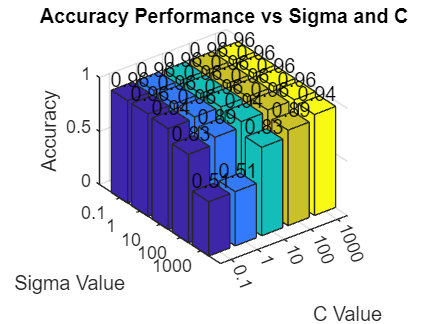

% Plot the 3D bar graph
[CGrid, SigmaGrid] = meshgrid(C, sigma);
figure;
hBar = bar3(scores');
set(gca, 'XTickLabel', C, 'YTickLabel', sigma);
xlabel('C Value');
ylabel('Sigma Value');
zlabel('Accuracy');
title('Accuracy Performance vs Sigma and C');

% Add text labels to bars
for i = 1:size(scores, 1)
    for j = 1:size(scores, 2)
        zVal = scores(i, j);
        text(i, j, zVal, num2str(zVal, '%.2f'), ...
             'HorizontalAlignment', 'center', ...
             'VerticalAlignment', 'bottom');
    end
end

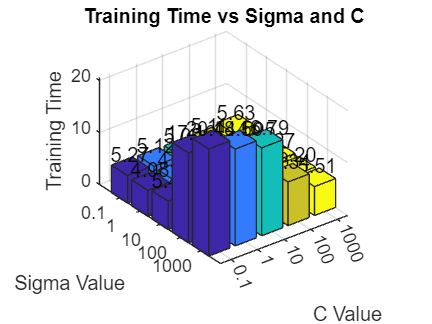

figure;
hBar = bar3(times');
set(gca, 'XTickLabel', C, 'YTickLabel', sigma);
xlabel('C Value');
ylabel('Sigma Value');
zlabel('Training Time');
title('Training Time vs Sigma and C');

% Add text labels to bars
for i = 1:size(times, 1)
    for j = 1:size(times, 2)
        zVal = times(i, j);
        text(i, j, zVal, num2str(zVal, '%.2f'), ...
             'HorizontalAlignment', 'center', ...
             'VerticalAlignment', 'bottom');
    end
end

## Save SVM model

svmClassifierSaved = svmClassifier{1};
save('trainedSVM.mat', 'svmClassifierSaved');